## Лаба 6. Критерий Найквиста и системы с запаздыванием

### Задание 2. Коэффициент усиления

p = 1; q = 4; n = 4; m = 1; i = 2;
s = tf('p');

### Объект W1

***Случай k = 1***

count = 1;

simTimeStart = 0;
simTimeEnd = 50;
dt = 0.02;
t_sim = simTimeStart:dt:simTimeEnd;

k = 1;
W1 = (k*(s-2))/(s^2 +6*s +5);
W1_closed = feedback(W1,1);

%%% АФЧХ %%%
figure;
k = 1;
nyquist(W1)
xlabel('Magnitude (dB)');
ylabel('Phase (degrees)');
title(strcat('АФЧХ, k=', num2str(k)))
save_file("nyquist_task21_object"+count);

%%% АЧХ-ФЧХ %%%
freqs = linspace(0, 5, 2000);
omega = 2*pi*freqs;
[mag, phase, ~] = bode(W1, omega); % omega is in rad/s
mag = squeeze(mag); % Magnitude (absolute, not dB)
phase = squeeze(phase); % Phase (degrees)

figure;
plot(freqs, mag, 'b', 'LineWidth', 1.5);
xlabel('Frequency (Hz)');
ylabel('Magnitude (dB)');
grid on;
title('АЧХ for open loop')
legend('sim', 'Location', 'best')
save_file("freq_ampl2_closed"+count);

figure;
plot(freqs, phase, 'b', 'LineWidth', 1.5);
xlabel('Frequency (Hz)');
ylabel('Phase (degrees)');
title('ФЧХ for open loop')
grid on;
legend('sim', 'Location', 'best')
save_file("freq_phase2_closed"+count);

%%% Переходные функции %%%
figure;
[y_sim, t_out] = step(W1_closed, t_sim);
plot(t_out, y_sim, 'b', 'LineWidth', 1.5);
grid on
title('step responce for closed loop')
legend('sim', 'Location', 'best')
save_file("step_responce21_closed"+count);

***Случай k = 2 ***

k = 2;
W1 = (k*(s-2))/(s^2 +6*s +5);
W1_closed = feedback(W1,1);

figure;
nyquist(W1)
xlabel('Magnitude (dB)');
ylabel('Phase (degrees)');
title(strcat('АФЧХ, k=', num2str(k)))
save_file("nyquist_task22_object"+count);

%%% Переходные функции %%%
figure;
[y_sim, t_out] = step(W1_closed, t_sim);
plot(t_out, y_sim, 'b', 'LineWidth', 1.5);
grid on
title('step responce for closed loop')
legend('sim', 'Location', 'best')
save_file("step_responce22_closed"+count);

***Случай k = 3 ***

k = 3;
W1 = (k*(s-2))/(s^2 +6*s +5);
W1_closed = feedback(W1,1);
figure;
nyquist(W1)
% grid on;
xlabel('Magnitude (dB)');
ylabel('Phase (degrees)');
title(strcat('АФЧХ, k=', num2str(k)))
save_file("nyquist_task23_object"+count);

%%% Переходные функции %%%
figure;
[y_sim, t_out] = step(W1_closed, t_sim);
plot(t_out, y_sim, 'b', 'LineWidth', 1.5);
grid on
title('step responce for closed loop')
legend('sim', 'Location', 'best')
save_file("step_responce23_closed"+count);

***Случай k = 6***

%%% АФЧХ %%%
k = 6;
W1 = (k*(s-2))/(s^2 +6*s +5);
W1_closed = feedback(W1,1);
figure;
nyquist(W1)
% grid on;
xlabel('Magnitude (dB)');
ylabel('Phase (degrees)');
title(strcat('АФЧХ, k=', num2str(k)))
save_file("nyquist_task24_object"+count);

%%% Переходные функции %%%
figure;
[y_sim, t_out] = step(W1_closed, t_sim);
plot(t_out, y_sim, 'b', 'LineWidth', 1.5);
grid on
title('step responce for closed loop')
legend('sim', 'Location', 'best')
save_file("step_responce24_closed"+count);
%%% АФЧХ %%%
k = 2.5;
W1 = (k*(s-2))/(s^2 +6*s +5);
W1_closed = feedback(W1,1);
figure;
nyquist(W1)
% grid on;
xlabel('Magnitude (dB)');
ylabel('Phase (degrees)');
title(strcat('АФЧХ, k=', num2str(k)))
save_file("nyquist_task25_object"+count);


figure;
k = 1.0;
W1 = (k*(s-2))/(s^2 +6*s +5);
h = bodeplot(W1)
grid on;
h.showCharacteristic('AllStabilityMargins');
save_file("log_nyquist_task2_object"+count);

### Объект W2

***Случай k = 1***

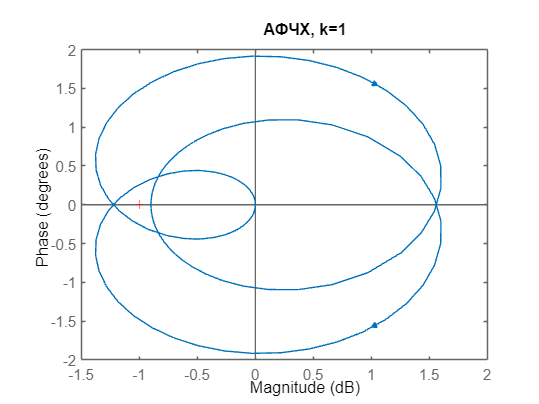

count = 2;
s = tf('p');
simTimeStart = 0;
simTimeEnd = 500;
dt = 0.01;
t_sim = simTimeStart:dt:simTimeEnd;

k = 1;
W2 = k*(-9*s^3 + 16*s^2 -6*s)/(10*s^3 + 12*s^2 +5*s +1);
W2_closed = feedback(W2,1);

%%% АФЧХ %%%
figure;
k = 1;
nyquist(W2)
xlabel('Magnitude (dB)');
ylabel('Phase (degrees)');
title(strcat('АФЧХ, k=', num2str(k)))
save_file("nyquist_task21_object"+count);

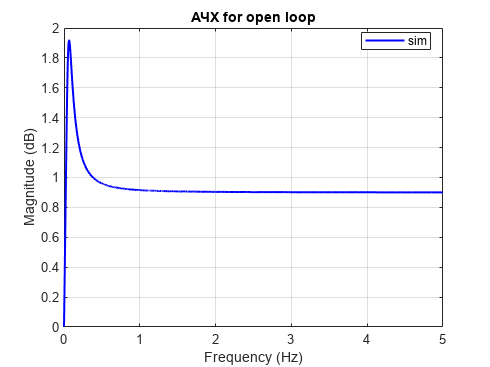


%%% АЧХ-ФЧХ %%%
freqs = linspace(0, 5, 8000);
omega = 2*pi*freqs;
[mag, phase, ~] = bode(W2, omega); % omega is in rad/s
mag = squeeze(mag); % Magnitude (absolute, not dB)
phase = squeeze(phase); % Phase (degrees)

figure;
plot(freqs, mag, 'b', 'LineWidth', 1.5);
xlabel('Frequency (Hz)');
ylabel('Magnitude (dB)');
grid on;
title('АЧХ for open loop')
legend('sim', 'Location', 'best')
save_file("freq_ampl2_closed"+count);

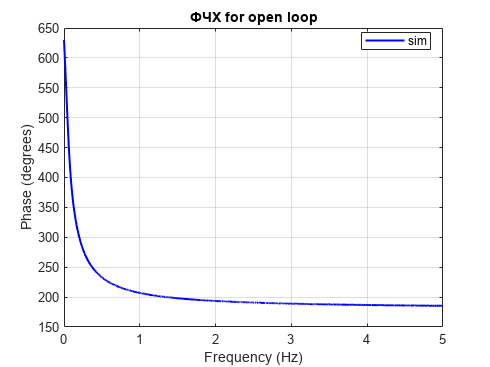


figure;
plot(freqs, phase, 'b', 'LineWidth', 1.5);
xlabel('Frequency (Hz)');
ylabel('Phase (degrees)');
title('ФЧХ for open loop')
grid on;
legend('sim', 'Location', 'best')
save_file("freq_phase2_closed"+count);

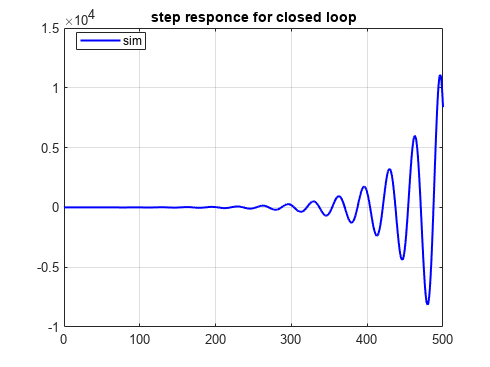


%%% Переходные функции %%%
figure;
[y_sim, t_out] = step(W2_closed, t_sim);
plot(t_out, y_sim, 'b', 'LineWidth', 1.5);
grid on
title('step responce for closed loop')
legend('sim', 'Location', 'best')
save_file("step_responce21_closed"+count);

***Случай k = 3***

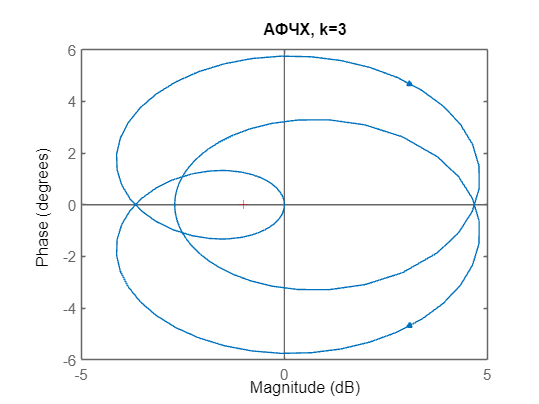

k = 3;
W2 = k*(-9*s^3 + 16*s^2 -6*s)/(10*s^3 + 12*s^2 +5*s +1);
W2_closed = feedback(W2,1);

figure;
nyquist(W2)
xlabel('Magnitude (dB)');
ylabel('Phase (degrees)');
title(strcat('АФЧХ, k=', num2str(k)))
save_file("nyquist_task22_object"+count);

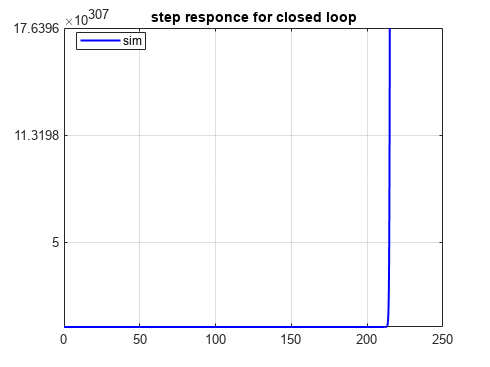


%%% Переходные функции %%%
figure;
[y_sim, t_out] = step(W2_closed, t_sim);
plot(t_out, y_sim, 'b', 'LineWidth', 1.5);
grid on
title('step responce for closed loop')
legend('sim', 'Location', 'best')
save_file("step_responce22_closed"+count);

***Случай k = 10 ***

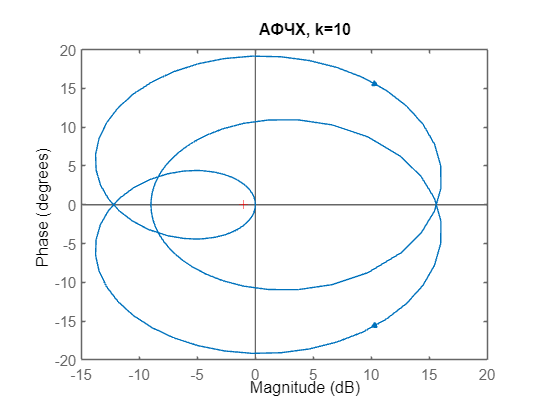

k = 10;
W2 = k*(-9*s^3 + 16*s^2 -6*s)/(10*s^3 + 12*s^2 +5*s +1);
W2_closed = feedback(W2,1);
figure;
nyquist(W2)
% grid on;
xlabel('Magnitude (dB)');
ylabel('Phase (degrees)');
title(strcat('АФЧХ, k=', num2str(k)))
save_file("nyquist_task23_object"+count);

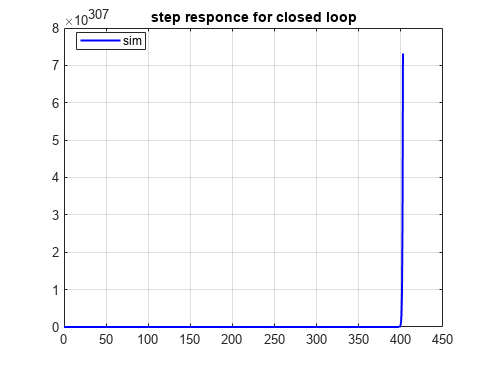


%%% Переходные функции %%%
figure;
[y_sim, t_out] = step(W2_closed, t_sim);
plot(t_out, y_sim, 'b', 'LineWidth', 1.5);
grid on
title('step responce for closed loop')
legend('sim', 'Location', 'best')
save_file("step_responce23_closed"+count);

***Случай k = 0.6***

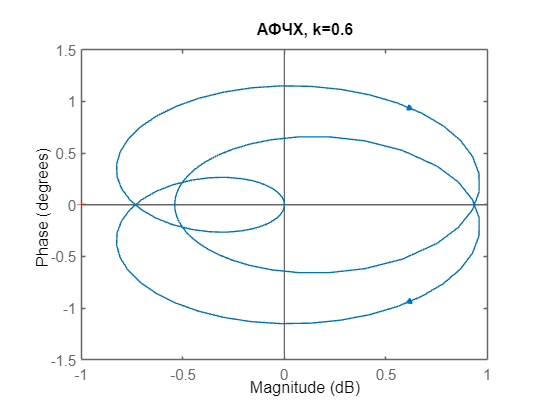

%%% АФЧХ %%%
k = 0.6;
W2 = k*(-9*s^3 + 16*s^2 -6*s)/(10*s^3 + 12*s^2 +5*s +1);
W2_closed = feedback(W2,1);
figure;
nyquist(W2)
% grid on;
xlabel('Magnitude (dB)');
ylabel('Phase (degrees)');
title(strcat('АФЧХ, k=', num2str(k)))
save_file("nyquist_task24_object"+count);

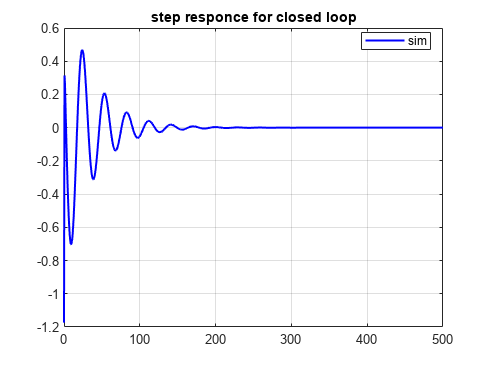


%%% Переходные функции %%%
figure;
[y_sim, t_out] = step(W2_closed, t_sim);
plot(t_out, y_sim, 'b', 'LineWidth', 1.5);
grid on
title('step responce for closed loop')
legend('sim', 'Location', 'best')
save_file("step_responce24_closed"+count);

***Случай k = 20***

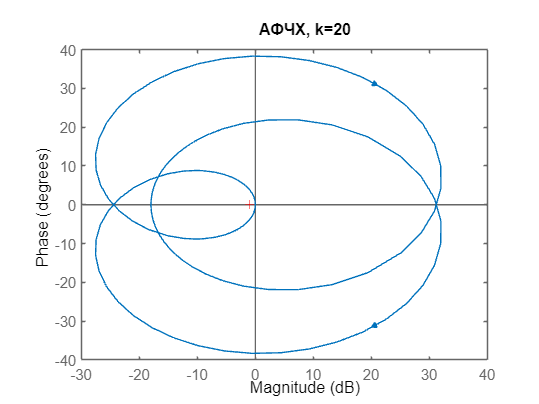

k = 20;
W2 = k*(-9*s^3 + 16*s^2 -6*s)/(10*s^3 + 12*s^2 +5*s +1);
W2_closed = feedback(W2,1);
figure;
nyquist(W2)
% grid on;
xlabel('Magnitude (dB)');
ylabel('Phase (degrees)');
title(strcat('АФЧХ, k=', num2str(k)))
save_file("nyquist_task25_object"+count);

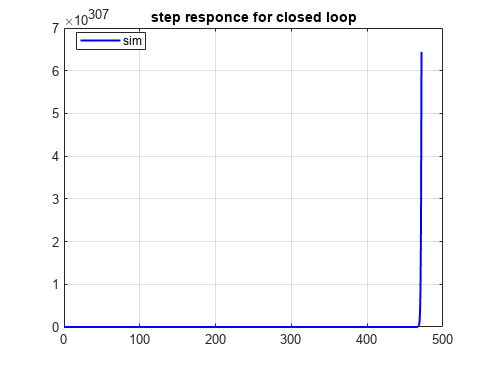


%%% Переходные функции %%%
figure;
[y_sim, t_out] = step(W2_closed, t_sim);
plot(t_out, y_sim, 'b', 'LineWidth', 1.5);
grid on
title('step responce for closed loop')
legend('sim', 'Location', 'best')
save_file("step_responce25_closed"+count);

***Случай k = 0.2***

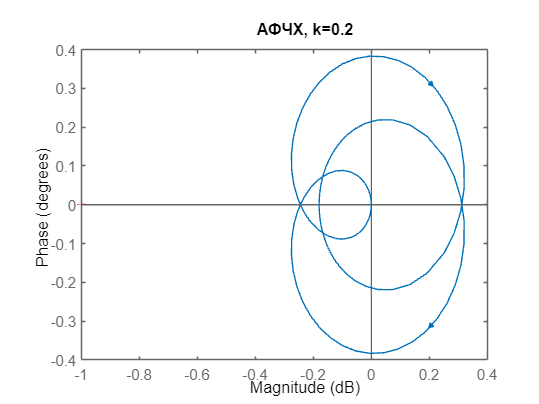

%%% АФЧХ %%%
k = 0.2;
W2 = k*(-9*s^3 + 16*s^2 -6*s)/(10*s^3 + 12*s^2 +5*s +1);
W2_closed = feedback(W2,1);
figure;
nyquist(W2)
% grid on;
xlabel('Magnitude (dB)');
ylabel('Phase (degrees)');
title(strcat('АФЧХ, k=', num2str(k)))
save_file("nyquist_task26_object"+count);

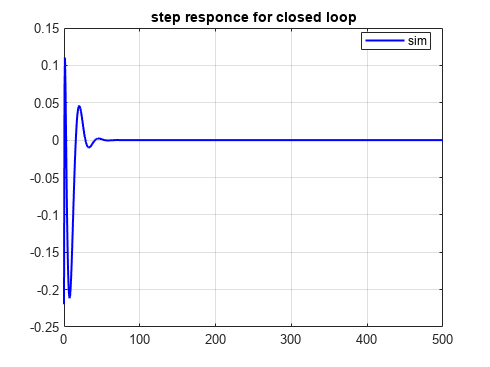


%%% Переходные функции %%%
figure;
[y_sim, t_out] = step(W2_closed, t_sim);
plot(t_out, y_sim, 'b', 'LineWidth', 1.5);
grid on
title('step responce for closed loop')
legend('sim', 'Location', 'best')
save_file("step_responce26_closed"+count);

***Случай k = 0.9***

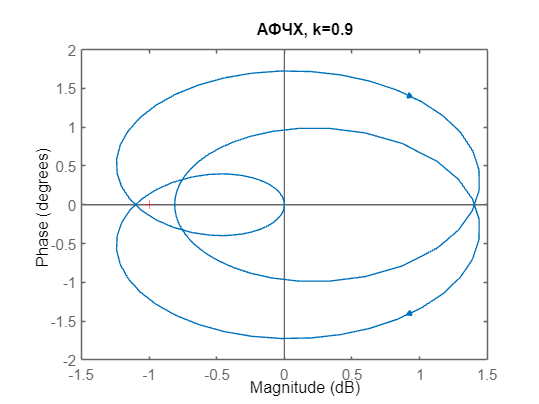

%%% АФЧХ %%%
k = 0.9;
W2 = k*(-9*s^3 + 16*s^2 -6*s)/(10*s^3 + 12*s^2 +5*s +1);
W2_closed = feedback(W2,1);
figure;
nyquist(W2)
% grid on;
xlabel('Magnitude (dB)');
ylabel('Phase (degrees)');
title(strcat('АФЧХ, k=', num2str(k)))
save_file("nyquist_task27_object"+count);

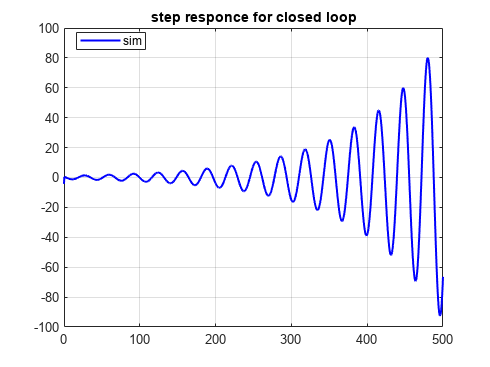


%%% Переходные функции %%%
figure;
[y_sim, t_out] = step(W2_closed, t_sim);
plot(t_out, y_sim, 'b', 'LineWidth', 1.5);
grid on
title('step responce for closed loop')
legend('sim', 'Location', 'best')
save_file("step_responce27_closed"+count);

% %%% АФЧХ %%%
% k = 1;
% W2 = k*(-9*s^3 + 16*s^2 -6*s)/(10*s^3 + 12*s^2 +5*s +1);
% W2_closed = feedback(W2,1);
% figure;
% nyquist(W2)
% % grid on;
% xlabel('Magnitude (dB)');
% ylabel('Phase (degrees)');
% title(strcat('АФЧХ, k=', num2str(k)))
% save_file("nyquist_task25_object"+count);

figure;
k = 1;
W2 = k*(-9*s^3 + 16*s^2 -6*s)/(10*s^3 + 12*s^2 +5*s +1);
h = bodeplot(W2)


h =

	resppack.bodeplot



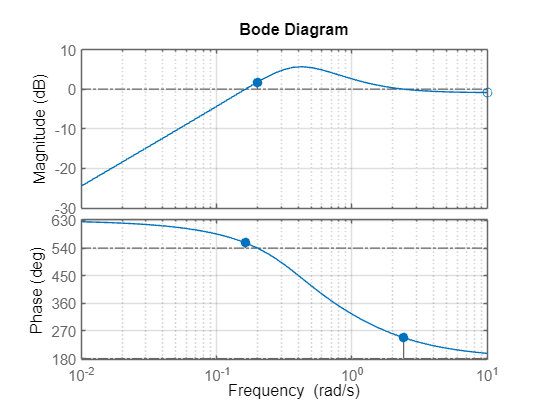

grid on;
h.showCharacteristic('AllStabilityMargins');
save_file("log_nyquist_task2_object"+count);


allmargin(W2)

ans = struct with fields:
     GainMargin: [0.8156 1.1111]
    GMFrequency: [0.1998 Inf]
    PhaseMargin: [17.1819 68.1384]
    PMFrequency: [0.1628 2.4063]
    DelayMargin: [1.8423 0.4942]
    DMFrequency: [0.1628 2.4063]
         Stable: 0


## Функции

**Save file in the folder**

function save_file(name)
    path = 'D:\Math\control_theory\linear_systems_labs\lab6\latex6\images';
    fullpath = fullfile(path, name);
    saveas(gcf, fullpath, 'png');
end

**Рисовать комплексные числа**

function plotComplexRoots(roots)
    % Input: 'roots' is a vector containing up to 5 complex numbers.
    
    % Ensure the figure is properly configured
    figure;
    hold on;
    grid on;
    axis equal;
    title(' ');
    xlabel('Re', 'Interpreter', 'latex');
    ylabel('Imag', 'Interpreter', 'latex');
    
    % Define colors for up to 5 roots
    colors = {'r', 'g', 'b', 'm', 'c'};
    
    % Plot each root with unique color and LaTeX label
    for i = 1:min(length(roots), 5)
        plot(real(roots(i)), imag(roots(i)), 'o', ...
            'MarkerSize', 6, 'MarkerFaceColor', colors{i}, ...
            'DisplayName', ['$\lambda_' num2str(i) '$']);
    end
    
    % Compute limits with offset for better visibility
    real_vals = real(roots);
    imag_vals = imag(roots);
    real_min = min(real_vals) - 5;
    real_max = max(real_vals) + 5;
    imag_min = min(imag_vals) - 5;
    imag_max = max(imag_vals) + 5;
    
    % Set axis limits
    xlim([real_min, real_max]);
    ylim([imag_min, imag_max]);
    
    % Add a vertical magenta line at x = 0
    xline(0, 'm--', 'LineWidth', 1.5, 'DisplayName','vertical');
    
    % Add a legend with LaTeX interpreter
    legend('Interpreter', 'latex', 'Location', 'best');
    
    hold off;
end

% 
% simTimeStart = 0;
% simTimeEnd = 5;
% 
% l1 = -2 + 3j; l2 = -2 - 3j; l3= -10;
% out = sim(modelName, 'StopTime', num2str(simTimeEnd), 'FixedStep',num2str(step));
% t = out.simout.Time;
% y_out = out.simout.Data; g_show = ones(1, length(t))'; 
% 
% h = figure; set(h,'DefaultAxesFontSize', 12, 'DefaultAxesFontName','Times New Roman');
% subplot(2,1,1);
% plot(t, y_out, 'r');
% title('output');   
% xlabel('time [s]');                  
% ylabel('f(t)');                      
% grid on;
% legend('y(t)');
% 
% subplot(2,1,2);
% plotComplex(l1,l2,l3)
% save_file(h, 'output_task2_exp12')
% 
% % Вычисление стационарного значения
% y_final = y_out(end);
% % перерегулирование по стандартной формуле
% y_max = max(y_out);
% overshoot = ((y_max - y_final) / y_final) * 100
% % Время, когда функция достигает 98% от конечного значения
% threshold = 0.99 * y_final; 
% transient_time = t( find(y_out >= threshold, 1) )